### Question 1

Calculates the alternating sum of 20 and 100.

n = 20;
x = myalternatesum(n)

x = 10

n = 100;
x = myalternatesum(n)

x = 50

### Question 2

Calculates the value for  0.5((sqrt(3) - 1)^2 depending on the format (long or short).

f = @(x) 0.5*((x-1).^2);
format long;
f(sqrt(3))

ans =    0.267949192431123


format short;
f(sqrt(3))

ans = 0.2679

### Question 3

Samples 10 and 100 equally spaced values between 0 and 1 using the previously defined function in question 2.

x10 = linspace(0,1,10);
y10 = f(x10)

y10 =     0.5000    0.3951    0.3025    0.2222    0.1543    0.0988    0.0556    0.0247    0.0062         0


x100 = linspace(0,1,100);
y100 = f(x100)

y100 =     0.5000    0.4900    0.4800    0.4702    0.4604    0.4508    0.4412    0.4318    0.4225    0.4132    0.4041    0.3951    0.3861    0.3773    0.3686    0.3600    0.3514    0.3430    0.3347    0.3265    0.3184    0.3104    0.3025    0.2947    0.2870    0.2794    0.2719    0.2645    0.2572    0.2500    0.2429    0.2359    0.2290    0.2222    0.2155    0.2090    0.2025    0.1961    0.1898    0.1837    0.1776    0.1716    0.1657    0.1600    0.1543    0.1488    0.1433    0.1379    0.1327    0.1275


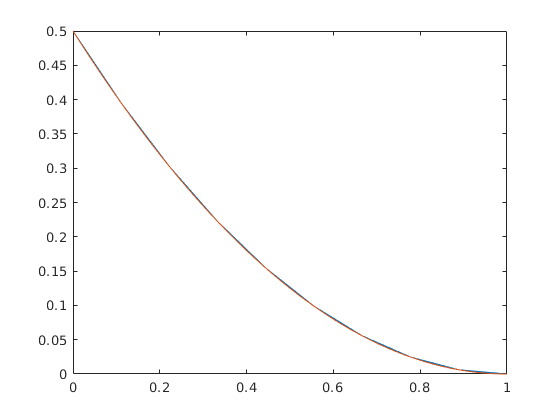


plot(x10, y10, x100, y100)

### Question 4

Different approximations for the forward difference formula.

fPrime = @(x, h) (f(x + h) - f(x))/h

fPrime = function_handle with value:
    @(x,h)(f(x+h)-f(x))/h


x = 1.1;
h = 0.1

h = 0.1000

fPrime(x, h)

ans = 0.1500

h = 0.01

h = 0.0100

fPrime(x, h)

ans = 0.1050

h = 0.001

h = 1.0000e-03

fPrime(x, h)

ans = 0.1005

### Question 5

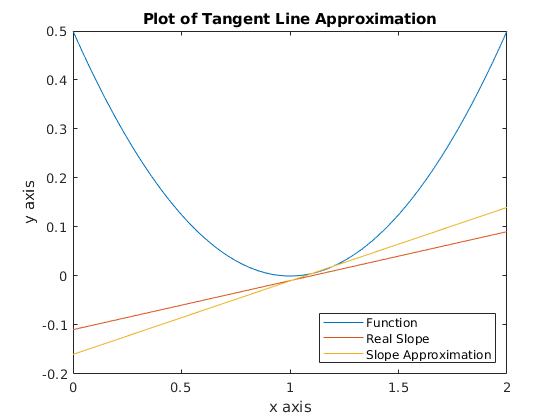

x100 = linspace(0,2,100);
y100f = f(x100);
tangent = @(x) (0.1*x - 0.1095);
y100t = tangent(x100);
approx = @(x) (fPrime(1.1, 0.1)*(x - 1.1) + f(1.1));
y100approx = approx(x100);

plot(x100, y100f, x100, y100t, x100, y100approx)
title('Plot of Tangent Line Approximation')
legend({'Function','Real Slope','Slope Approximation'},'Location','southeast')
xlabel('x axis')
ylabel('y axis')

function s = myalternatesum(n)
    s = 0;
    for i = 1:n
        s = s + ((-1).^i * i);
    end
end